syms t
multiplier = 3.36

multiplier = 3.3600

u = t/multiplier;
h = 0.24;
x = 0.6561*sin(u);
y = 0.3280*sin(2*u);
vx = simplify(diff(x));
vy = simplify(diff(y));
speed = simplify(sqrt(vx^2+vy^2));
Tx = simplify(vx/speed);
Ty = simplify(vy/speed);
qx = simplify(diff(Tx));
qy = simplify(diff(Ty));
q_norm = simplify(sqrt(qx^2+qy^2));
Nx = simplify(qx / q_norm);
Ny = simplify(qy / q_norm);
thetadot = simplify(Tx*qy - Ty*qx);
vl = simplify(speed - 0.5*h*thetadot);
vr = simplify(speed + 0.5*h*thetadot);
v1 = simplify((vr+vl)./2);
tlist = 0.01:0.01:(2*multiplier*pi);

blah = double(cumsum(diff(tlist).*(double(subs(v1,tlist(2:end))))));
blah(end)

ans = 3.9969

max(double(subs(vx,tlist)))

ans = 0.1953

max(double(subs(vy,tlist)))

ans = 0.1952

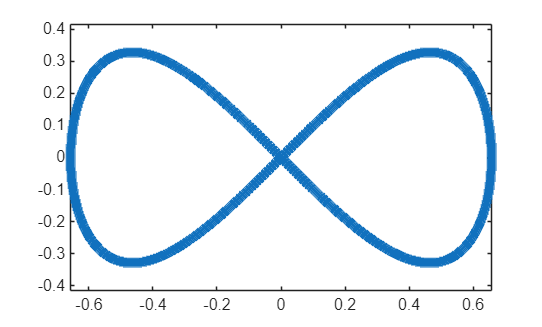

figure();
plot(double(subs(x,tlist)),double(subs(y,tlist)),"*")
movegui('center');
axis equal
hold off

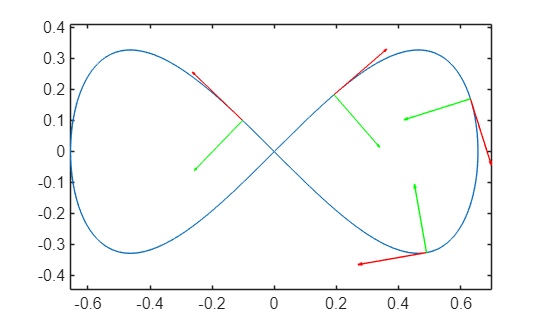


figure();
plot(double(subs(x,tlist)),double(subs(y,tlist)))
movegui('center');
axis equal
hold on
t_vals = 1:multiplier:multiplier*4;

for i = t_vals
    quiver(subs(x,i),subs(y,i),subs(Tx,i)/4,subs(Ty,i)/4,"r");
end
for i = t_vals
    quiver(subs(x,i),subs(y,i),subs(Nx,i)/4,subs(Ny,i)/4,"g");
end
hold off


figure();
tlist_1 = tlist(1:floor(length(tlist)/2))

tlist_1 =     0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900    0.5000


tlist_2 = tlist(floor(length(tlist)/2)+1:end)

tlist_2 =    10.5600   10.5700   10.5800   10.5900   10.6000   10.6100   10.6200   10.6300   10.6400   10.6500   10.6600   10.6700   10.6800   10.6900   10.7000   10.7100   10.7200   10.7300   10.7400   10.7500   10.7600   10.7700   10.7800   10.7900   10.8000   10.8100   10.8200   10.8300   10.8400   10.8500   10.8600   10.8700   10.8800   10.8900   10.9000   10.9100   10.9200   10.9300   10.9400   10.9500   10.9600   10.9700   10.9800   10.9900   11.0000   11.0100   11.0200   11.0300   11.0400   11.0500


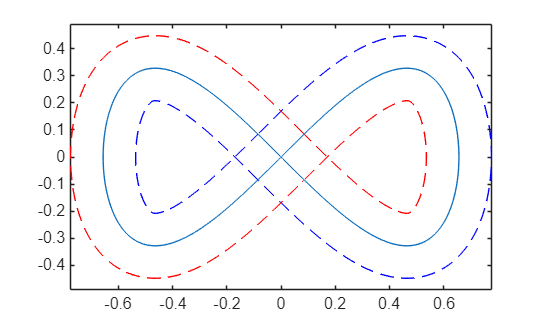


plot(double(subs(x,tlist)),double(subs(y,tlist)))
hold on
plot(double(subs(x,tlist_1))+double(subs(Nx,tlist_1)).*0.12,double(subs(y,tlist_1))+double(subs(Ny,tlist_1)).*0.12,"r--")
plot(double(subs(x,tlist_1))-double(subs(Nx,tlist_1)).*0.12,double(subs(y,tlist_1))-double(subs(Ny,tlist_1)).*0.12,"b--")
plot(double(subs(x,tlist_2))+double(subs(Nx,tlist_2)).*0.12,double(subs(y,tlist_2))+double(subs(Ny,tlist_2)).*0.12,"b--")
plot(double(subs(x,tlist_2))-double(subs(Nx,tlist_2)).*0.12,double(subs(y,tlist_2))-double(subs(Ny,tlist_2)).*0.12,"r--")
movegui('center');
axis equal
hold off

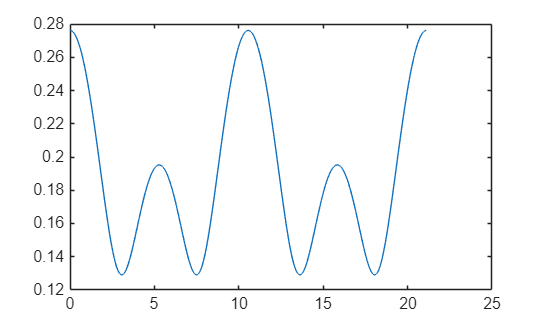


figure();
plot(tlist,double(subs(v1,tlist)))
movegui('center');
hold off

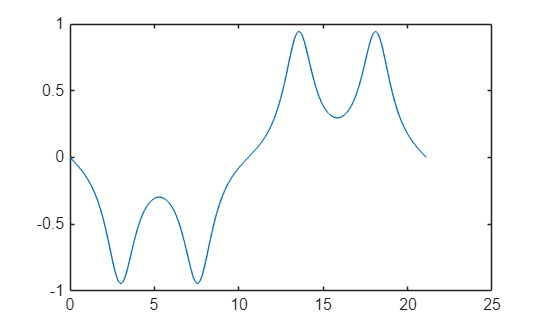


figure();
plot(tlist,double(subs(thetadot,tlist)))
movegui('center');
hold off

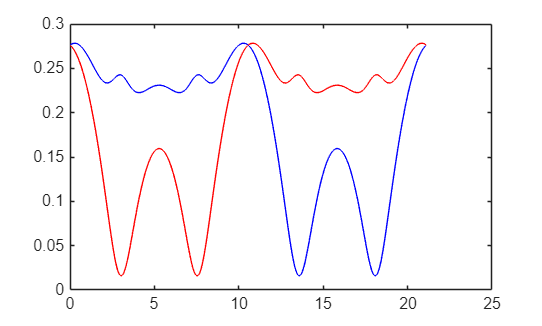


figure();
plot(tlist,double(subs(vl,tlist)),"b")
hold on
plot(tlist,double(subs(vr,tlist)),"r")
movegui('center');
hold off


tlist = 0.1:0.1:(pi*multiplier*4);
vl_list = double(subs(vl,tlist(1:length(tlist)/2)));
vr_list = double(subs(vr,tlist(1:length(tlist)/2)));
cat(2, vl_list, double(subs(vl,tlist(length(tlist)/2:end))))

ans =     0.2774    0.2781    0.2782    0.2778    0.2768    0.2754    0.2735    0.2712    0.2685    0.2655    0.2622    0.2588    0.2552    0.2516    0.2481    0.2447    0.2416    0.2388    0.2366    0.2348    0.2338    0.2335    0.2338    0.2349    0.2365    0.2383    0.2402    0.2417    0.2426    0.2426    0.2416    0.2397    0.2372    0.2343    0.2314    0.2287    0.2264    0.2246    0.2234    0.2228    0.2226    0.2229    0.2235    0.2244    0.2254    0.2264    0.2275    0.2285    0.2294    0.2301


cat(2, vr_list, double(subs(vr,tlist(length(tlist)/2:end))))

ans =     0.2742    0.2717    0.2685    0.2647    0.2603    0.2552    0.2495    0.2431    0.2361    0.2284    0.2202    0.2113    0.2018    0.1916    0.1810    0.1697    0.1579    0.1455    0.1327    0.1195    0.1060    0.0923    0.0787    0.0653    0.0527    0.0412    0.0313    0.0235    0.0184    0.0161    0.0168    0.0203    0.0263    0.0342    0.0434    0.0536    0.0641    0.0747    0.0851    0.0951    0.1045    0.1133    0.1214    0.1287    0.1353    0.1411    0.1461    0.1504    0.1538    0.1564




%connect to the neato
neatov3.connect('192.168.16.66');

Deleting previous Neato connection.
Connecting to the Neato.
Testing connection.
Connection successful.


encoders = zeros(0,3);
tic;
for i = 1:length(tlist)
    neatov3.setVelocities(vl_list(i), vr_list(i));
     sensors = neatov3.receive();

    encoders(end+1,:) = [toc, sensors.encoders(1), sensors.encoders(2)];
    pause(0.1);
end

Index exceeds the number of array elements. Index must not exceed 211.


neatov3.setVelocities(0,0);
neatov3.receive()
neatov3.disconnect();

